clc;clear;close all
addpath('~/Documents/AIFNET/testImg/')
prefix = "ILSVRC2012_val_0000";
surfix = ".JPEG";

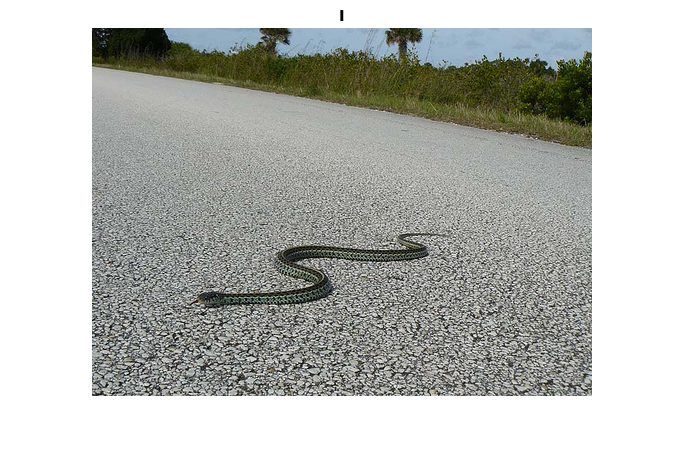

for i = 6
    filename = strcat(prefix, num2str(i, '%04d'), surfix);
    I = imread(filename);
    [m, n, ~] = size(I);
    figure, imshow(I);
    title('I');

    mask = zeros(m, n);
    x_bound = [max(0, floor(m/2)-100), min(m, floor(m/2)+99)];
    y_bound = [max(0, floor(n/2)-100), min(n, floor(n/2)+99)];
    mask(x_bound, y_bound) = 1;

## segmentation method1


%     bw = activecontour(I, mask, 500);
%     figure, imshow(bw);
%     title('BW');
%     se = strel('disk',3);
%     openBW = imopen(bw,se);
%     figure, imshow(openBW);
%     title('openBW')
%     openBW = repmat(uint8(openBW), [1, 1, 3]);


## segmentation method2

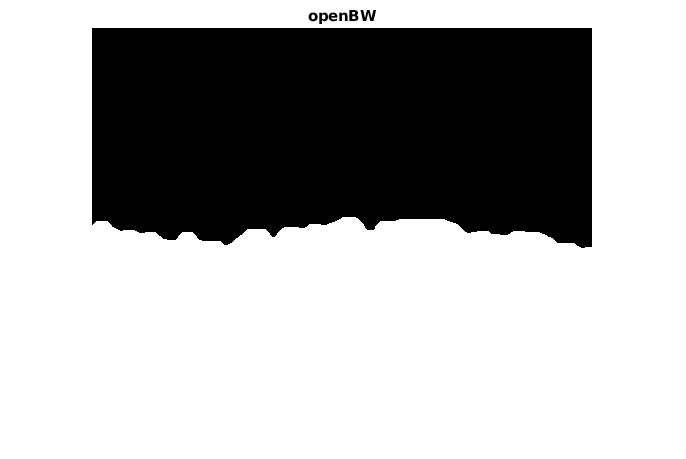

% lab_I  = rgb2lab(I);
% ab = lab_I(:,:,2:3);
% ab = im2single(ab);
% nColors = 2;
% % repeat the clustering 3 times to avoid local minima
% pixel_labels = imsegkmeans(ab,nColors,'Threshold', 10);
% mask1 = pixel_labels==1;
% figure, imshow(mask1);
% title('Mask 1');
wavelength = 2.^(0:5) * 3;
orientation = 0:45:135;
g = gabor(wavelength,orientation);
I_bw = rgb2gray(im2single(I));
gabormag = imgaborfilt(I_bw,g);
%montage(gabormag,'Size',[4 6])
for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),3*sigma); 
end
%montage(gabormag,'Size',[4 6])

[X,Y] = meshgrid(1:n,1:m);
featureSet = cat(3,I_bw,gabormag,X,Y);
L2 = imsegkmeans(featureSet,2,'NormalizeInput',true);
se = strel('disk',10);
openBW = imopen(L2-1,se);
figure, imshow(openBW, []);
title('openBW')

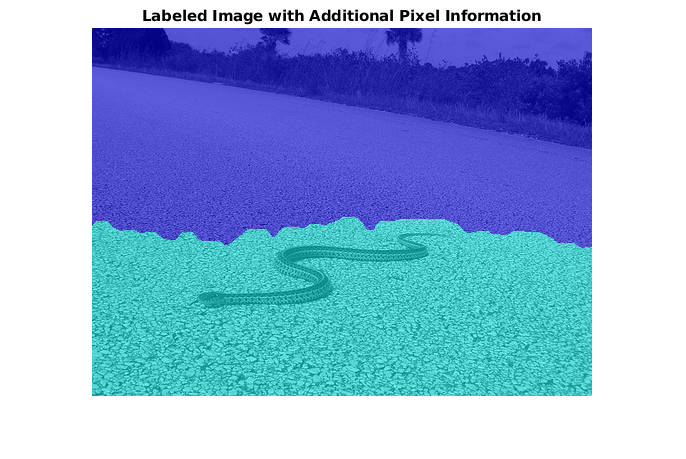

C = labeloverlay(I_bw,openBW+1);
imshow(C)
title('Labeled Image with Additional Pixel Information')

end